clear;
clc;

syms R mu a e real
syms n t real
syms x0 y0 z0 dx0 dy0 dz0 real
syms J [1 4] real
syms INC Omega omega theta_0 real
    assumeAlso([J2 > 0, R > 0, mu > 0, a > 0, e > 0, e < 1, n > 0]);

% Variables dependientes del tiempo
delta = 2*(theta_0 - e*(1 + sqrt(1 - e^2))*sin(theta_0));
sd2 = sin(delta/2);
cd2 = cos(delta/2);
snt = sin(n*t);
cnt = cos(n*t);

theta_c = omega + theta_0 - 2*e*sd2;
u = theta_c + n*t + 2*e*(sd2*cnt + cd2*snt);

% Sistema Euler-Hill a sistema inercial
Rz_RAAN = [cos(Omega), -sin(Omega), 0;
           sin(Omega),  cos(Omega), 0;
                    0,           0, 1];
Rx_INC = [1,        0,         0;
          0, cos(INC), -sin(INC);
          0, sin(INC),  cos(INC)];
Rz_u = [cos(u), -sin(u), 0;
        sin(u),  cos(u), 0;
             0,       0, 1];

R_EUtoI = Rz_RAAN * Rx_INC * Rz_u;

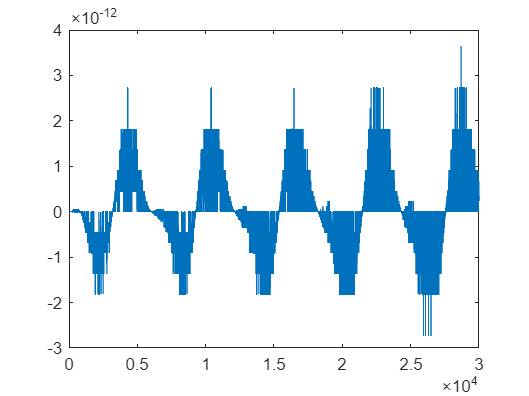

t = linspace(0, 3e4, 1e5);
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
e = 0.01;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
Omega   = deg2rad(0);
omega   = deg2rad(30);
theta_0 = deg2rad(0);
x0   = 0;
y0   = 0;
z0   = 0;
dx0  = 0;
dy0  = 0;
dz0  = 0;

% Solución analítica en el sistema Euler-Hill
xJ2    = ((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*x0 + ((160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*160)).*dx0 + ((320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(a.*n.*(- 1 + e.^2).^4.*160)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(a.*n.*(- 1 + e.^2).^4.*160)).*J2;
yJ2    = (-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(a.*n.*(- 1 + e.^2).^4.*160)).*x0.*t + ((960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*x0 + ((160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(a.*n.*(- 1 + e.^2).^4.*160)).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*160)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0.*t + ((640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(a.*n.*(- 1 + e.^2).^4.*160)).*t.^2.*J2 + ((480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(a.*n.*(- 1 + e.^2).^4.*160)).*t.*J2 + ((140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*J2;
zJ2    = ((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*8)).*z0 + ((8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*8)).*dz0 + ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(a.*n.*(- 1 + e.^2).^4.*8)).*t.*J2 + ((48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(a.*n.*(- 1 + e.^2).^4.*8)).*J2;

xdotJ2 = ((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*x0 + ((160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*dx0 + ((320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(a.*n.*(- 1 + e.^2).^4.*160) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(a.*n.*(- 1 + e.^2).^4.*160)).*J2;
ydotJ2 = (-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*40)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(a.*(- 1 + e.^2).^4.*40)).*dx0 + ((40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*40)).*dy0 + ((30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(a.*(- 1 + e.^2).^4.*40)).*t.*J2 + ((5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*40)).*J2;
zdotJ2 = (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*8)).*z0 + ((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*8)).*dz0 + (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(a.*n.*(- 1 + e.^2).^4.*8)).*t.*J2 + ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(a.*n.*(- 1 + e.^2).^4.*8) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(a.*n.*(- 1 + e.^2).^4.*8)).*J2;


rhoJ2 = ((640.*a.*n - 640.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 2560.*a.*e.^2.*n.*cos(n.*t) - 3840.*a.*e.^4.*n.*cos(n.*t) + 2560.*a.*e.^6.*n.*cos(n.*t) - 640.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*x0 + ((320.*a.^2 - 320.*a.^2.*cos(n.*t) - 1280.*a.^2.*e.^2 + 1920.*a.^2.*e.^4 - 1280.*a.^2.*e.^6 + 320.*a.^2.*e.^8 + 1280.*a.^2.*e.^2.*cos(n.*t) - 1920.*a.^2.*e.^4.*cos(n.*t) + 1280.*a.^2.*e.^6.*cos(n.*t) - 320.*a.^2.*e.^8.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(160.*a.*n.*(e.^2 - 1).^4)).*J2;
phiJ2 = (-(960.*a.*e.^8.*n.^2 - 3840.*a.*e.^6.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^2.*n.^2 + 960.*a.*n.^2)./(160.*a.^2.*n.*(e.^2 - 1).^4)).*x0.*t + ((1280.*a.*n.*sin(n.*t).*e.^8 - 5120.*a.*n.*sin(n.*t).*e.^6 + 7680.*a.*n.*sin(n.*t).*e.^4 - 5120.*a.*n.*sin(n.*t).*e.^2 + 1280.*a.*n.*sin(n.*t))./(160.*a.^2.*n.*(e.^2 - 1).^4)).*x0 + (-(480.*n.*a.^2.*e.^8 - 1920.*n.*a.^2.*e.^6 + 2880.*n.*a.^2.*e.^4 - 1920.*n.*a.^2.*e.^2 + 480.*n.*a.^2)./(160.*a.^2.*n.*(e.^2 - 1).^4)).*dy0.*t + ((640.*sin(n.*t).*a.^2.*e.^8 - 2560.*sin(n.*t).*a.^2.*e.^6 + 3840.*sin(n.*t).*a.^2.*e.^4 - 2560.*sin(n.*t).*a.^2.*e.^2 + 640.*sin(n.*t).*a.^2)./(160.*a.^2.*n.*(e.^2 - 1).^4)).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(160.*a.^2.*n.*(e.^2 - 1).^4)).*t.^2.*J2 + ((480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(theta_0./2 - INC + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(omega - INC + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(omega - INC + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(omega - INC + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(160.*a.^2.*n.*(e.^2 - 1).^4)).*t.*J2 + ((140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(theta_0 - 2.*INC + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(160.*a.^2.*n.*(e.^2 - 1).^4)).*J2;
x_cyl = rhoJ2 .* cos(phiJ2);
y_cyl = rhoJ2 .* sin(phiJ2);

rhodotJ2 = ((640.*a.*n.^2.*sin(n.*t) - 2560.*a.*e.^2.*n.^2.*sin(n.*t) + 3840.*a.*e.^4.*n.^2.*sin(n.*t) - 2560.*a.*e.^6.*n.^2.*sin(n.*t) + 640.*a.*e.^8.*n.^2.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*x0 + ((320.*n.*sin(n.*t).*a.^2.*e.^8 - 1280.*n.*sin(n.*t).*a.^2.*e.^6 + 1920.*n.*sin(n.*t).*a.^2.*e.^4 - 1280.*n.*sin(n.*t).*a.^2.*e.^2 + 320.*n.*sin(n.*t).*a.^2)./(160.*a.*n.*(e.^2 - 1).^4)).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(2.*omega - 2.*INC + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4) - (60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*J2;
phidotJ2 = ((80.*a.*n - 640.*a.*n.*sin((n.*t)./2).^2 - 320.*a.*e.^2.*n + 480.*a.*e.^4.*n - 320.*a.*e.^6.*n + 80.*a.*e.^8.*n + 2560.*a.*e.^2.*n.*sin((n.*t)./2).^2 - 3840.*a.*e.^4.*n.*sin((n.*t)./2).^2 + 2560.*a.*e.^6.*n.*sin((n.*t)./2).^2 - 640.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(40.*a.^2.*(e.^2 - 1).^4)).*x0 + (-(320.*a.^2.*sin((n.*t)./2).^2 - 40.*a.^2 + 160.*a.^2.*e.^2 - 240.*a.^2.*e.^4 + 160.*a.^2.*e.^6 - 40.*a.^2.*e.^8 - 1280.*a.^2.*e.^2.*sin((n.*t)./2).^2 + 1920.*a.^2.*e.^4.*sin((n.*t)./2).^2 - 1280.*a.^2.*e.^6.*sin((n.*t)./2).^2 + 320.*a.^2.*e.^8.*sin((n.*t)./2).^2)./(40.*a.^2.*(e.^2 - 1).^4)).*dy0 + ((30.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(40.*a.^2.*(e.^2 - 1).^4)).*t.*J2 + ((5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(omega - INC + theta_0).^2 + 5.*R.^2.*n.*sin(omega - INC + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(omega - INC + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(omega - INC + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(omega - INC + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega - INC + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(omega - INC + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(omega - INC + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega - INC + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(omega - INC + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(omega - INC + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(omega - INC + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(omega - INC + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(omega - INC + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(omega - INC + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(omega - INC + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega - INC + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(theta_0./2 - INC + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(40.*a.^2.*(e.^2 - 1).^4)).*J2;

plot(t, x_cyl - xJ2)

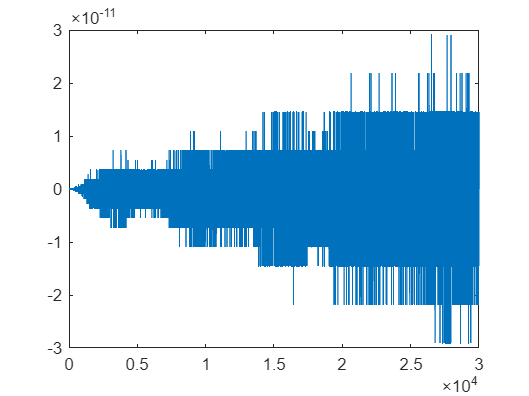

plot(t, y_cyl - yJ2)





% xJ2 = collect(xJ2, [x0 y0 z0 dx0 dy0 dz0 t J2]);
%     J2xx0     = simplifyExpresion((diff(xJ2,  x0)), 1000, 1000)
%     J2xdx0    = simplifyExpresion((diff(xJ2, dx0)), 1000, 1000)
%     J2xdy0    = simplifyExpresion((diff(xJ2, dy0)), 1000, 1000)
%     J2xJ2     = collect(simplify(diff(xJ2,  J2) / R^2 * a * (1 - e^2)^4), [e^2, e]);
%         p1 = diff(diff(J2xJ2/2, e), e);
%         p2 = diff(J2xJ2 - p1*e^2, e);
%         p3 = J2xJ2 - p1*e^2 - p2*e;
%         J2xJ2e0    = simplifyExpresion(p3, 1000, 1000)
%         J2xJ2e1    = simplifyExpresion(p2, 1000, 1000)
%         J2xJ2e2    = simplifyExpresion(p1, 1000, 1000)
% 
% xdotJ2 = collect(xdotJ2, [x0 y0 z0 dx0 dy0 dz0 t J2]);
%     J2xdotx0  = simplifyExpresion((diff(xdotJ2,  x0)), 1000, 1000)
%     J2xdotdx0 = simplifyExpresion((diff(xdotJ2, dx0)), 1000, 1000)
%     J2xdotdy0 = simplifyExpresion((diff(xdotJ2, dy0)), 1000, 1000)
%     J2xdotJ2  = collect(simplify(diff(xdotJ2,  J2) / R^2 / n * a * (1 - e^2)^4), [e^2, e]);
%         p1 = diff(diff(J2xdotJ2/2, e), e);
%         p2 = diff(J2xdotJ2 - p1*e^2, e);
%         p3 = J2xdotJ2 - p1*e^2 - p2*e;
%         J2xdotJ2e0 = simplifyExpresion(p3, 1000, 1000)
%         J2xdotJ2e1 = simplifyExpresion(p2, 1000, 1000)
%         J2xdotJ2e2 = simplifyExpresion(p1, 1000, 1000)
% 
% yJ2 = collect(yJ2, [x0 y0 z0 dx0 dy0 dz0 t J2]);
%     J2yx0  = simplifyExpresion((diff(yJ2,  x0)), 1000, 1000)
%     J2ydx0 = simplifyExpresion((diff(yJ2, dx0)), 1000, 1000)
%     J2ydy0 = simplifyExpresion((diff(yJ2, dy0)), 1000, 1000)
%     J2yJ2     = collect(simplify(diff(yJ2,  J2) / R^2 * a * (1 - e^2)^4), [e^2, e]);
%         p1 = diff(diff(J2yJ2/2, e), e);
%         p2 = diff(J2yJ2 - p1*e^2, e);
%         p3 = J2yJ2 - p1*e^2 - p2*e;
%         J2yJ2e0    = simplifyExpresion(p3, 1000, 1000)
%         J2yJ2e1    = simplifyExpresion(p2, 1000, 1000)
%         J2yJ2e2    = simplifyExpresion(p1, 1000, 1000)
% 
% ydotJ2 = collect(ydotJ2, [x0 y0 z0 dx0 dy0 dz0 t J2]);
%     J2ydotx0  = simplifyExpresion((diff(ydotJ2,  x0)), 1000, 1000)
%     J2ydotdx0 = simplifyExpresion((diff(ydotJ2, dx0)), 1000, 1000)
%     J2ydotdy0 = simplifyExpresion((diff(ydotJ2, dy0)), 1000, 1000)
%     J2ydotJ2  = collect(simplify(diff(ydotJ2,  J2) / R^2 / n * a * (1 - e^2)^4), [e^2, e]);
%         p1 = diff(diff(J2ydotJ2/2, e), e);
%         p2 = diff(J2ydotJ2 - p1*e^2, e);
%         p3 = J2ydotJ2 - p1*e^2 - p2*e;
%         J2ydotJ2e0 = simplifyExpresion(p3, 1000, 1000)
%         J2ydotJ2e1 = simplifyExpresion(p2, 1000, 1000)
%         J2ydotJ2e2 = simplifyExpresion(p1, 1000, 1000)
% 
% zJ2 = collect(zJ2, [x0 y0 z0 dx0 dy0 dz0 t J2]);
%     J2zz0  = simplifyExpresion((diff(zdotJ2,  z0)), 1000, 1000)
%     J2zdz0 = simplifyExpresion((diff(zdotJ2, dz0)), 1000, 1000)
%     J2zJ2     = collect(simplify(diff(zJ2,  J2) / R^2 * a * (1 - e^2)^4), [e^2, e]);
%         p1 = diff(diff(J2zJ2/2, e), e);
%         p2 = diff(J2zJ2 - p1*e^2, e);
%         p3 = J2zJ2 - p1*e^2 - p2*e;
%         J2zJ2e0    = simplifyExpresion(p3, 1000, 1000)
%         J2zJ2e1    = simplifyExpresion(p2, 1000, 1000)
%         J2zJ2e2    = simplifyExpresion(p1, 1000, 1000)
% 
% zdotJ2 = collect(zdotJ2, [x0 y0 z0 dx0 dy0 dz0 t J2]);
%     J2zdotz0  = simplifyExpresion((diff(zdotJ2,  z0)), 1000, 1000)
%     J2zdotdz0 = simplifyExpresion((diff(zdotJ2, dz0)), 1000, 1000)
%     J2zdotJ2  = collect(simplify(diff(zdotJ2,  J2) / R^2 / n * a * (1 - e^2)^4), [e^2, e]);
%         p1 = diff(diff(J2zdotJ2/2, e), e);
%         p2 = diff(J2zdotJ2 - p1*e^2, e);
%         p3 = J2zdotJ2 - p1*e^2 - p2*e;
%         J2zdotJ2e0 = simplifyExpresion(p3, 1000, 1000)
%         J2zdotJ2e1 = simplifyExpresion(p2, 1000, 1000)
%         J2zdotJ2e2 = simplifyExpresion(p1, 1000, 1000)

% Solución analítica en el sistema inercial
rI = R_EUtoI * [   xJ2;    yJ2;    zJ2];
vI = R_EUtoI * [xdotJ2; ydotJ2; zdotJ2];

xJ2    = rI(1);
yJ2    = rI(2);
zJ2    = rI(3);
xdotJ2 = vI(1);
ydotJ2 = vI(2);
zdotJ2 = vI(3);

r_cyl = R_EUtoI * [   x_cyl;    y_cyl;    zJ2];
x_cyl    = r_cyl(1);
y_cyl    = r_cyl(2);